# 实验三

## 内容1

 
%系统建立
num = 1;
den = [1,1,1];
sys = tf(num,den)

damp(den)
%阶跃相应
step(sys)
[y,t,x] = step(sys)
%冲激响应
impulse(sys)
[y,t,x] = impulse(sys)

## 一阶系统

 
num = 1;
den = [1,1];
%建立系统
sys = tf(num,den);
t = 0:0.01:10;
%定义正弦输入
f = sin(t);
lsim(sys,f,t)
title('')

## 二阶系统

 
clc;
clear;
sys1 = tf(1,[1,0.2,1]);
sys2 = tf(1,[1,0.4,1]);
sys3 = tf(1,[1,0.6,1]);
sys4 = tf(1,[1,0.8,1]);
sys5 = tf(1,[1,1.0,1]);
sys6 = tf(1,[1,1.2,1]);
sys7 = tf(1,[1,1.4,1]);
sys8 = tf(1,[1,1.6,1]);
sys9 = tf(1,[1,1.8,1]);
sys10 = tf(1,[1,2.0,1]);
step(sys1,sys2,sys3,sys4,sys5,sys6,sys7,sys8,sys9 ...
    ,sys10)
legend('sigma = 0.1','sigma = 0.2','sigma = 0.3' ...
    ,'sigma = 0.4','sigma = 0.5','sigma = 0.6' ...
    ,'sigma = 0.7','sigma = 0.8','sigma = 0.8' ...
    ,'sigma = 1.0')
title('')

## 二阶系统分析

 
clc
clear
num = 10;
den = [1,2,10];
%G = tf(num,den);
G = zpk([],[-1+3*i,-1-3*i],10);
damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.00e+00 + 3.00e+00i     3.16e-01       3.16e+00         1.00e+00    
 -1.00e+00 - 3.00e+00i     3.16e-01       3.16e+00         1.00e+00    


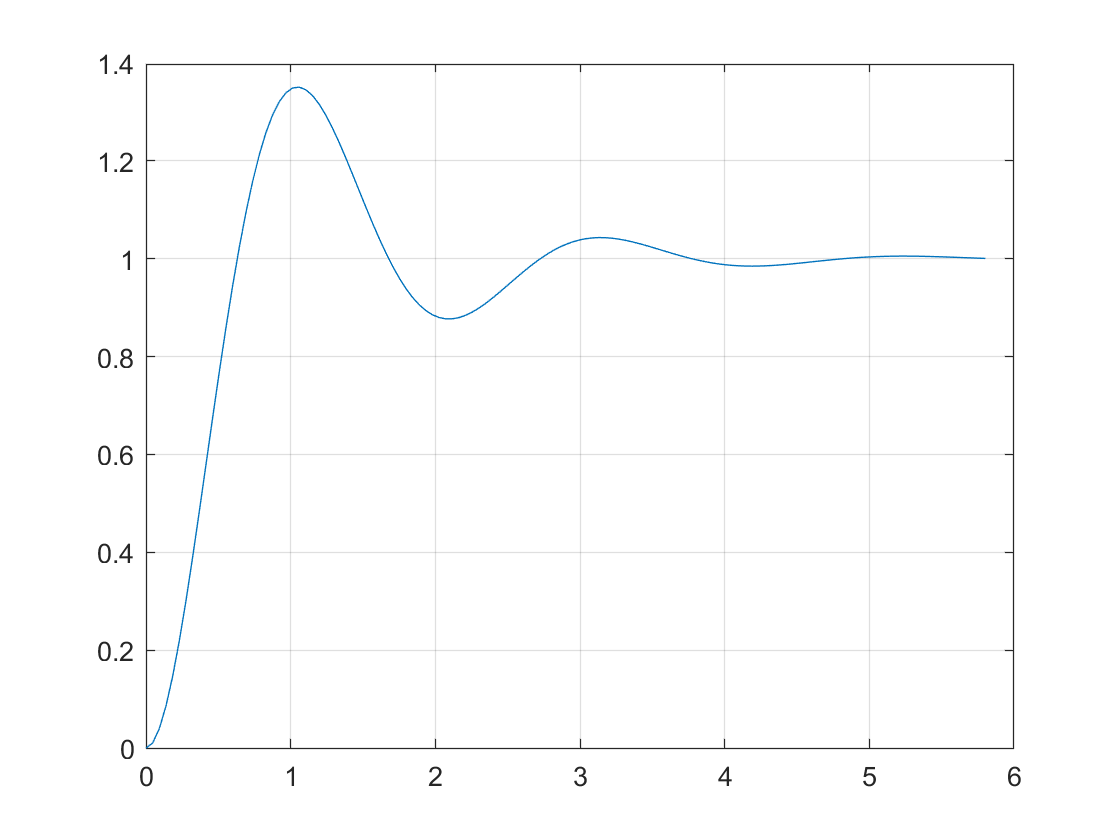

%计算最大峰值时间和对应超调量
C = dcgain(G);
[y,t] = step(G);
plot(t,y)
grid on;

%取得最大峰值
[Y,k] = max(y);
%取得最大峰值时间
timeopeak = t(k)

timeopeak = 1.0592

%计算峰值
overshoot = Y

overshoot = 1.3507

%计算超调量
percentovershoot = 100*(Y-C)/C

percentovershoot = 35.0670


n = 1;
while y(n)<C
n = n+1;
end
risetime = t(n)

risetime = 0.6447

i = length(t);

%计算稳态响应时间5%
while(y(i)>0.95*C)&(y(i)<1.05*C)
    i = i-1;
end
settingtime = t(i)

settingtime = 2.4868


% 计算稳态响应时间2%
% while(y(i)>0.98*C)&(y(i)<1.02*C)
%     i = i-1;
% end
% settingtime = t(i)

## 实验5

 
clear
clc
sys = tf(3,[2,5,3])

sys =
 
         3
  ---------------
  2 s^2 + 5 s + 3
 
Continuous-time transfer function.



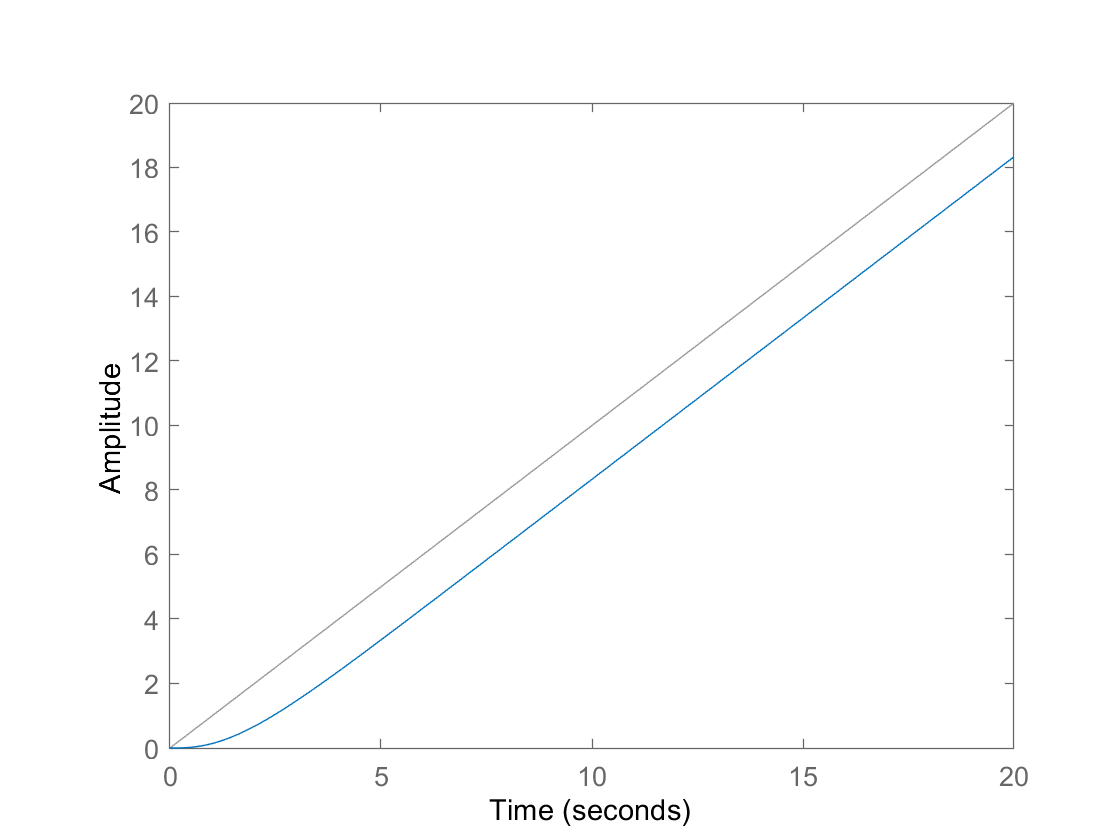

t = 0:0.1:20;
u = t;
lsim(sys,u,t)
title('')